# Relational Operators and Indexing into Variables

In this Live Script you'll practice indexing into variables and using logical indexing to access or change data based on conditions you try. Run the script section by section. Using a pen and paper, write down what you think the result of each line of code will be before running the section and see if you're right! If after reviewing this document and the output, you're confused by a line of code, post your question to the forums.

## Indexing into Vectors

### Row and Column Vectors

To index into a vector, you only need to specify the indices to extract. This works if the vector is a row vector or a column vector. For example, let's revisit the example from the video:

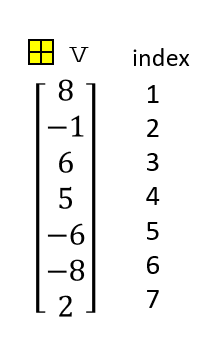

This is a **column** vector because it has a single column. The code below creates two vectors containing the exact same numbers. The first is a column vector, the second a row vector.

vColumn = [8; -1; 6; 5; -6; -8; 2]

You create a row vector by separating elements with commas instead of semi-colons, or you can use the transpose operator as shown here.

vRow = vColumn'

Because vColumn and vRow are both vectors, the commands below extract the exact same numbers. However, look at the size of the outputs. 

first4c = vColumn(1:4)
first4r = vRow(1:4)

### Common Indexing Errors

There are a few common indexing errors. 

- Using numbers that are **not** positive integers as an index

- Using a number bigger than the largest possible index

Recognizing the error messages associated with these errors will help you quickly identify and correct mistakes. 

Execute this section to see the error message returned when the index is not a positive integer. The error message states array because this condition must be true for vectors, matrices, and arrays of 3 or more dimensions. 

vRow(-2)

Execute this section to see the error message when the index is larger than the number of elements. Notice that the error message shows the number of elements, in this case 7, to help you find the error.

vRow(11)

### Size, Length, and the `end `Keyword

Usually, you'll want your code to work regardless of the exact size of the data. 

**Length**

If you know that you're working with a vector, the [length](https://www.mathworks.com/help/matlab/ref/length.html) function will return the number of elements in the vector (be careful using this function with matrices - see below!). Try the length function on both `vRow `and `vColumn`.

n = length(vRow)

You can use the information to ensure you don't make the mistake of providing an index value greater than the number or array elements. For example, the code code below uses `n` to extract the last 3 elements of `vRow`. `n` in this case is 7, so `n-2:n` creates a vector `[5, 6, 7]` of indices to extract from `vRow`.

last3r = vRow(n-2:n)

`end Keyword`

There are many reasons to know how big your data is, but if you want to extract the last element or elements you can use the `end` keyworkd. Using `end` is just like using a number for the index, and is automatically interpreted to be the largest possible value the index can take in that direction.

last3c = vColumn(end-2:end)

**Size**

The `length` function is great for vectors, but it does not distinguish between row vectors and columns vectors...and what about matrices? That is where the `size `function comes in. It returns a vector output where the first element is the number of rows in the variable and the second element is the number of columns (if you have a higher dimensional array, there will be more than two elements in the output).

Notice that the length of `vRow` and `vColumn` are the same, but their sizes are different.

sR = size(vRow)
sC = size(vColumn)

Now, what about that matrix? Before running this section, see if you can determine what the output of the `length` and `size` functions will be.

M = [1:4; 5:8; 9:12]
sM = size(M)
lM = length(M)

What did you expect the length of `M` to be? The `length` function will always return the value of the largest dimension, in this case the number of columns. When working with matrices, it's best to use the `size` function to remove any ambiguity. 

## Indexing into Matrices

Accessing elements from matrices is similar to accessing elements from vectors, but matrices require two indices to specify the elements: one for the rows and one for the columns.

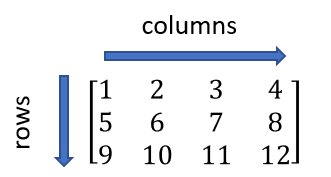

Before running this section, examine the code below and write down what elements will be returned. Then run the section to see if you're right.

M = [1:4; 5:8; 9:12]
M(2,3)
M(1,:)
M(end, end)
M(:, end-1)
M(1:2, 2:3)
M([1 3], [1 4])
M(4, 3)

The row and column indices are independent and can be scalars or vectors. Also, notice how the result can be a scalar, row vector, column vector, or matrix. Finally, read the error message when the row index is larger than the size in that direction. 

## cRelational Operators and Logical Indexing

### Relational Operators

In many cases, you won't know which indices you want to access, but will need access elements based on a condition. Here is a list of relational operators. 

- ` ==   `element-by-element equality check. Returns a logical variable the same size as the operands

- ` ~=`      element-by-element check for not equal to

- ` >, <, >=, <=   `element-by-element check for greater/less than, and greater/less than or equal to

-   `&`       AND operator - use to combine two conditions with AND. Returns true if both conditions are true

-   `|`       OR operator - use to combine two conditions with OR. Returns true if one or both conditions are true

The left and right side of these operators must be the same size or you'll get an error. 

The example below creates a vector of student exam scores and student names. A common use of relational operators is to create a logical vector to use for indexing into another variable. Let's see this in action. 

**Run this section** to create two variables for this example.

examScores = [92; 87; 72; 81; 66; 94; 77; 83; 59; 80; 75; 91; 64];
names = ["Brandon"; "Nikola"; "Michael"; "Maria"; "Cris"; "Renee"; "Amanda"; "Adam"; "John"; "Matt"; "Heather"; "Erin"; "Craig"];

The code below creates logical vectors to determine the locations of exam scores that fall into a specified range to create a letter grade: A, B, C, D, or F. Before running this section, try to guess what the output will be. Look at the variables in the workspace to see if you're correct.

Agrades = examScores >= 90;  % Creates a 13 element column vector that is true (1) at index 1, 6, and 12.
Bgrades = examScores < 90 & examScores >= 80;
Cgrades = examScores < 80 & examScores >= 70;
Dgrades = examScores < 70 & examScores >= 60;
Fgrades = examScores < 60;

### Logical Indexing

Now there should be 5 logical vectors in your Workspace that are true for elements where the specified condition was true. You can use these vectors to find the students in each category.

Astudents = names(Agrades)
Bstudents = names(Bgrades)
Fstudents = names(Fgrades)

Finally, let's assume those students with a grade of F leave the course. Use the NOT operator, `~`, to get the remaining students.

remainingStudents = names(~Fgrades)

Recall that the variables on either side of a relational operator must be the same size. Run this section to see the error message. The error message tells us "Matrix dimensions must agree" because `names` is 13x1 and `remainingStudents` is 12x1 

names == remainingStudents

## Putting it all together

Assume you want to find the student with the maximum grade. The max function has an optional 2nd output that returns the index of the maximum in the vector. In this case, idx is the actual value of the index and not a logical vector.

[val, idx] = max(examScores)
topStudent = names(idx)

What happens if you tried `names(val)` instead?

### Apply Concepts to the Weather Event Data

Now apply these concepts to the weather events data. The code below finds the most damaging event in the 2013 data set and the event narrative for the observation. As in the lecture video, the code uses the ismissing function to replace missing cost data with 0. Then the code calculates the total cost and adds it to the table.

events = importStormData("StormEvents_2013.csv");
events.Property_Cost(ismissing(events.Property_Cost)) = 0;
events.Crop_Cost(ismissing(events.Crop_Cost)) = 0;
events.Total_Cost = events.Property_Cost + events.Crop_Cost;

Find event type and narrative of the most damaging event in the data.

[maxDamage, eventIdx] = max(events.Total_Cost)
maxEventType = events.Event_Type(eventIdx)
maxEventNarrative = events.Event_Narrative(eventIdx)

The maximum event was part of an outbreak of tornadoes on the same day. Use logical indexing to find all tornadoes that occurred on that day. The line of code below gets the timestamp of the event with the most damage, then uses the `day` function with the "dayofyear" option to return the day of the year the event occurred.

maxDay = day(events.Begin_Date_Time(eventIdx), "dayofyear")

Now, find the day of year for all events and use the `==` operator to find all events that occurred on `maxDay`. Combine those events with the & operator for to select the events matching the maxEventType. How many tornado events are listed in the table for this day?

d = day(events.Begin_Date_Time, "dayofyear");
tornadoOutbreak = events(d == maxDay & events.Event_Type == maxEventType, :)

## Challenge Activities

Go back and use your own import function that includes the State variable. 

- If you live in the United States, use the relational operators to find the most damaging event in the state you live in. If you don't live in the United States, choose a state you've heard of, visited, or would like to visit. 

- Find all the related storm events for that day and state (for example you could combine Thunderstorm Wind and Tornado)

- If geographic location information is included in the data, create a visualization of the event locations for the storm outbreak for the most damaging event in the state you chose.

- Rerun the analysis on different years.